## Getting Started

### Installing

The toolbox can be install through MATLAB's ad-ons manager. Because this package depends on compiled code, in order to support mulltiple architectures, there are system specific files. To save space, you can run `igraph.postinstall()` after installing the toolbox or updating to clear out any files that are not useful on the current system. It's also possible to download a smaller architecture specific toolbox directly from the [github release page](https://github.com/DavidRConnell/matlab-igraph/releases), but this will require manually checking for updates.

### Set handlers

Handlers provide information about the current task. Handlers include "error", "warning", "progress", and "status". These can be turned on and off using the `igraph.verbose` command, with exception to the error handler, which must remain on since it's pertinent to understand why a statement failed. By default the warning handler is turned on and the progress and status handlers are left off. The warning handler *should* stay on as it provides information about potentially undesired or unexpected behavior, but it can be turned off in case there's a reason to silence them. The progress and status handlers provide non-problematic information about a currently running process; progress reports how far along a process is while status gives other useful information about the process that can't readily be represented as a percentage. These are off by default since they could be considered clutter when running many quicker functions. They can, however, be useful for longer running tasks. **Note:** not all functions provide progress reporting. For now we'll turn them on to see them in action:

igraph.verbose("progress", true);
igraph.verbose("status", true);

Inside this live script, progress reports appear on multiple lines but normally updates will overwrite the old data.

### Set a seed for reproducibility

If reproducible results are needed when using indeterminate methods, the random number generator's seed can be set.

igraph.rng(1234);

This does not impact MATLAB's random number generator. If numbers from both MATLAB's and igraph's random number generators are needed make sure to set both. Since both generators default to the same algorithm (MT199937), giving them the same seed will cause repeated numbers between them.

### Getting a graph to work with

There are several methods to get a graph: loading a graph from file (`igraph.load`), accessing a common graph (`igraph.famous)`, or generating a new graph (`igraph.generate`, for determinate graphs, or `igraph.randgame`, for stochastic graphs). Many of the methods for generating graphs have a set of optional arguments to modify the resulting graph. These optionals can be found by viewing `help igraph.generate` or `help igraph.randgame`. As an example, the Barabasi Bag method can be used to produce a graph with 15 nodes.

adj = igraph.randgame("BarabasiBag", nNodes = 15)

adj =    (2,1)        1
   (4,1)        1
   (6,1)        1
   (8,1)        1
   (3,2)        1
  (10,2)        1
   (5,3)        1
   (9,3)        1
   (7,6)        1
  (14,7)        1
  (11,8)        1
  (13,8)        1
  (15,8)        1
  (12,9)        1


Since the random number generator seed was set, the above command will always produce the same graph, otherwise the graph would vary from call-to-call.

#### Adjacency graph options

By default graphs are represented as a sparse matrix of doubles. Any function that returns an adjacency matrix has the option to use a full or sparse matrix and double or logical data type.

adj = igraph.rewire(adj, makeSparse=false, dtype="logical")


  Progress: [--------------------] 0%
  Progress: [####################] 100%


adj = 15×15 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0


Methods that both accept an adjacency matrix and return one behave different than those that only return a matrix. If a method accepts an adjacency matrix, the defaults for the output adjacency matrix will be to match the input.

### Saving and loading graphs

Once a graph is in memory, it can be saved to a file and then read back later. Either a graph file type or MATLAB's `mat` file type can be used. (See `help igraph.save` and `help igraph.load `for information about which graph files can be used, **Note:** there are some file types that can be saved to but cannot be loaded, to prevent challanges in retrieving data make sure you check if the graph type can be read.) The save and load functions will try to determine the file type based on the extension, but the `format` option can be used to explicity request a specific reader/writer.

igraph.save("rewired.txt", adj);
newAdj = igraph.load("rewired.txt");
isequal(adj, newAdj)

ans = logical
   1


Notice the new adjacency matrix is a sparse matrix of doubles despite a full matrix of logicals being saved. The representation of the data is kept completely separate from the data itself.

Clean up the left behind file.

delete("rewired.txt");

### A note about directedness

Graph's are stored as plain matrices without any additional metadata, as such, the directedness of the graph is not tracked. Instead, functions that depend on whether the graph is directed or not will use a test (`igraph.isdirected`), that will try to cleverly determine whether the graph is directed or not. This assumes the graph is undirected if it's symmetric or triangular. It's possible that a graph could be directed and fail the test of directedness. It should be unlikely, but in the case of a small graph with few edges or when starting with a symmetric graph that should be treated as directed the default behavior may be undesired. In these cases, the `isdirected` option should be explicitly set.

Additionally, in the case of undirected graphs, a symmetric graph, lower triangular, and upper triangular are treated as equivalent by the mxIgraph library. Because of this, when reading a graph from file, you may find the graph is the transpose (or half) of what was expected. For consistency and to match igraph functions, when generating or loading an undirected graph, only the lower half of the matrix will be collected.

### Plotting

Graphs can be plotted using different layout algorithms.

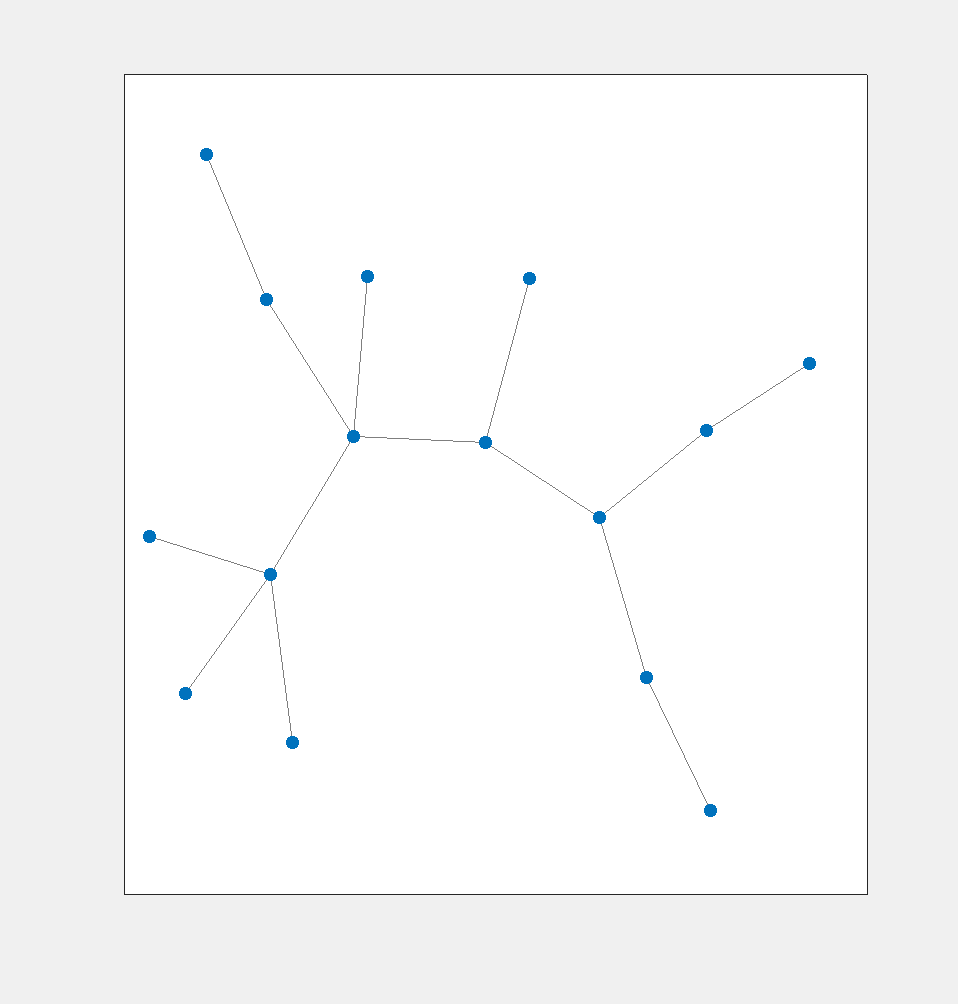

igraph.plot(adj, "kk");

Or a premade set of points can be provided to the plot method in order to customize the positions or reuse a layout for multiple plots.

layout = igraph.layout(adj, "graphopt");


  Progress: [--------------------] 0%
  Progress: [--------------------] 0%
  Progress: [#-------------------] 2%
  Progress: [#-------------------] 4%
  Progress: [##------------------] 6%
  Progress: [##------------------] 8%
  Progress: [##------------------] 10%
  Progress: [###-----------------] 12%
  Progress: [###-----------------] 14%
  Progress: [####----------------] 16%
  Progress: [####----------------] 18%
  Progress: [####----------------] 20%
  Progress: [#####---------------] 22%
  Progress: [#####---------------] 24%
  Progress: [######--------------] 26%
  Progress: [######--------------] 28%
  Progress: [######--------------] 30%
  Progress: [#######-------------] 32%
  Progress: [#######-------------] 34%
  Progress: [########------------] 36%
  Progress: [########------------] 38%
  Progress: [########------------] 40%
  Progress: [#########-----------] 42%
  Progress: [#########-----------] 44%
  Progress: [##########----------] 46%
  Progress: [##########-------

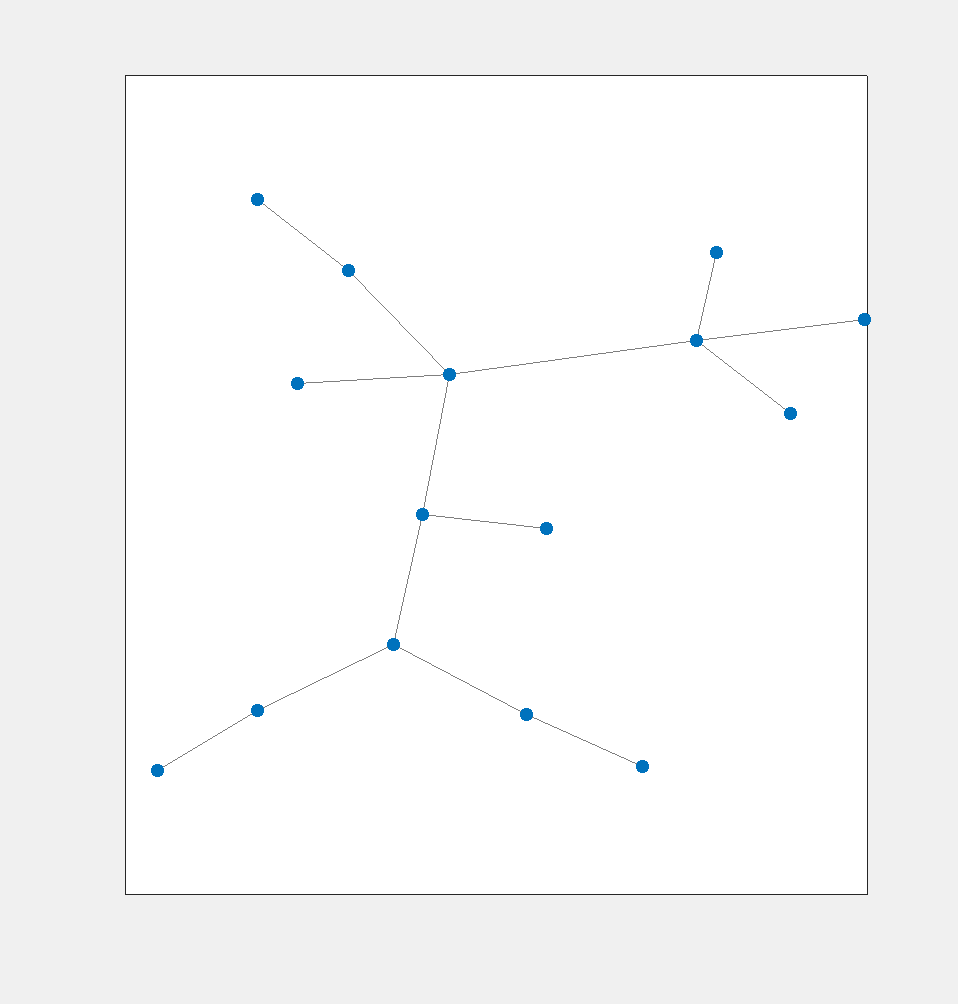

igraph.plot(adj, layout);

Membership and sizes can also be displayed.

adj = igraph.famous("zachary");
betweenness = igraph.centrality(adj, 'betweenness');


  Progress: [--------------------] 0%
  Progress: [#-------------------] 2.94118%
  Progress: [##------------------] 5.88235%
  Progress: [##------------------] 8.82353%
  Progress: [###-----------------] 11.7647%
  Progress: [###-----------------] 14.7059%
  Progress: [####----------------] 17.6471%
  Progress: [#####---------------] 20.5882%
  Progress: [#####---------------] 23.5294%
  Progress: [######--------------] 26.4706%
  Progress: [######--------------] 29.4118%
  Progress: [#######-------------] 32.3529%
  Progress: [########------------] 35.2941%
  Progress: [########------------] 38.2353%
  Progress: [#########-----------] 41.1765%
  Progress: [#########-----------] 44.1176%
  Progress: [##########----------] 47.0588%
  Progress: [##########----------] 50%
  Progress: [###########---------] 52.9412%
  Progress: [############--------] 55.8824%
  Progress: [############--------] 58.8235%
  Progress: [#############-------] 61.7647%
  Progress: [#############-------] 64.7059

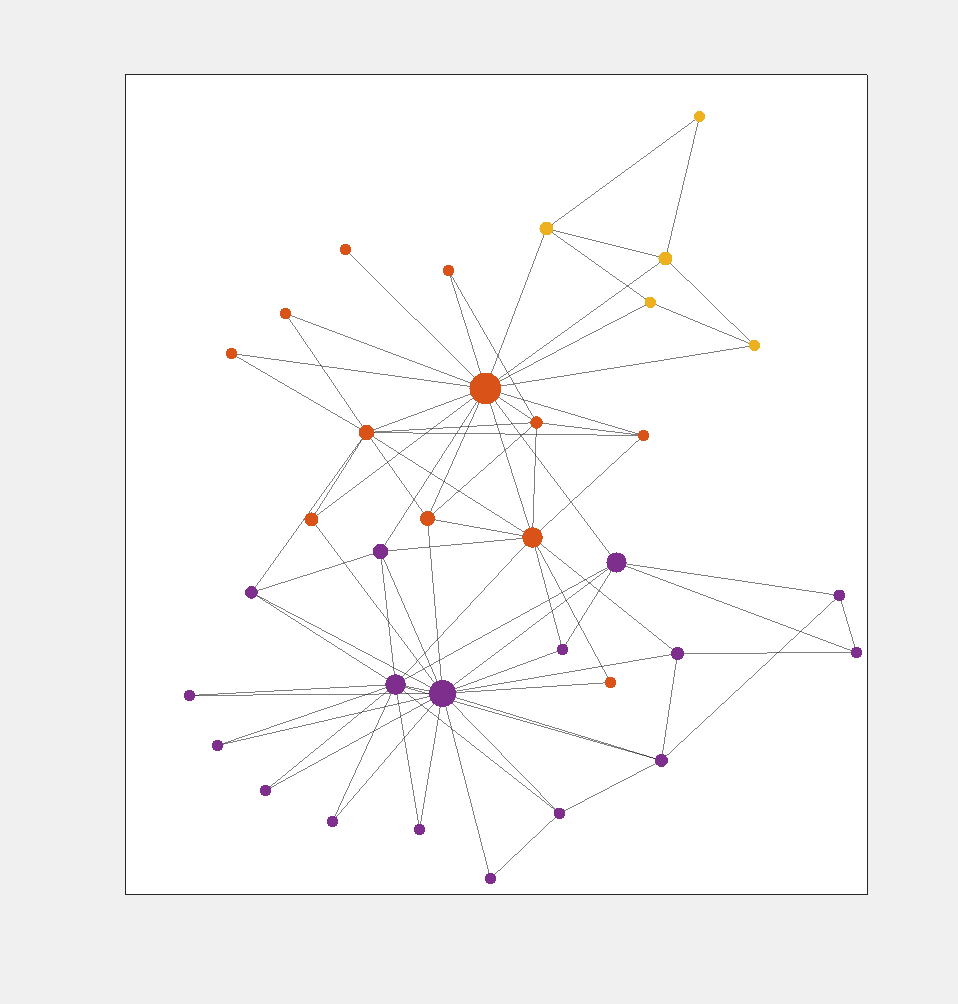

membership = igraph.cluster(adj, 'infomap');
igraph.plot(adj, 'kk', membership=membership, size=betweenness)

### A simple example: Community detection

Before starting, lets set a random seed and generate a graph based on a predetermined membership vector. Instead of using an igraph graph generation method, we can take advantage of base MATLAB to create our own generator. This will create an adjacency matrix with some number of communities and a constant probability for within community edges and between community edges.

MATLAB and igraph's random number generators are seperate but they default to the same algorithm. When using methods that depend on base MATLAB's random numbers as well as stochastic igraph methods, both MATLAB and igraph's random number generators should be set to ensure reproducibility, but if they are started with the same seed they will repeat each others values which could lead to unintended correlations.

rng(4920);        % Ensure reproducible results.
igraph.rng(2358); % Use a different seed for igraph's rng.

Define some constants for creating an example graph. The smaller `pIn` and greater `pOut`, the harder it will be for the community detection algorithms to reproduce the original structure.

nNodes = 50;
nCommunities = 6;
groundTruth = randi([1 nCommunities], 1, nNodes);
pIn = 0.6;
pOut = 0.2;

To generate the graph, we will use the ground truth as a template. Start with all within community edges existing and no between community edges.

adj = groundTruth == groundTruth';

Now we can randomly remove within community edges with probability `(1 - pIn)` and randomly add between community edges with probability `pOut`.

within = adj .* (rand(nNodes, nNodes) < pIn);
between = (1 - adj) .* (rand(nNodes, nNodes) < pOut);
adj = tril(within + between, -1); % -1 removes the diagonal (self-loops).

To visualize the new graph, plot the original graph along with it's known community structure. While the Fruchterman-Reingold algorithm should do a good job of seperating the communities on it's own, to give it a little help and to demonstrate costumizing templates, we'll provide an initial layout which places all members of a given community in a community starting position. 

Because the within community edge probability was set low, the graph's optimal solution may no longer match the ground truth, this would lead to the layout algorithm places vertices far from their original community. To force the algorithm to keep the nodes near the "ground truth" community, the layout's start temperature and number of iterations were significantly reduced from their defaults.

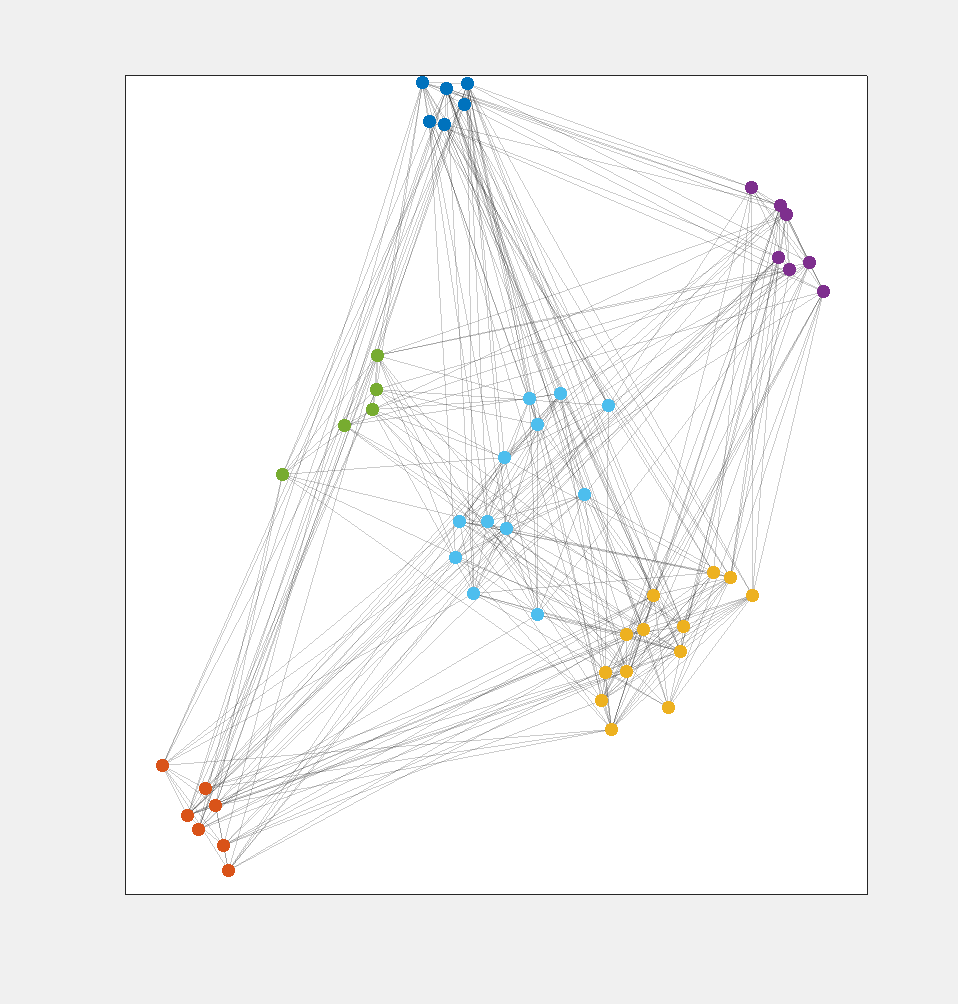

communityPositions = [randperm(nCommunities); randperm(nCommunities)]';
templateLayout = communityPositions(groundTruth, :);
layout = igraph.layout(adj, "fr", initial=templateLayout, startTemp=0.1, nIterations=15);
igraph.plot(adj, layout, membership=groundTruth, edgeAlpha=0.2);

#### Trying different community detection algorithms to predict the original community structure

communities.fastgreedy = igraph.cluster(adj, 'fastgreedy');


  Progress: [--------------------] 0%
  Progress: [#-------------------] 2.04082%
  Progress: [#-------------------] 4.08163%
  Progress: [##------------------] 6.12245%
  Progress: [##------------------] 8.16327%
  Progress: [###-----------------] 10.2041%
  Progress: [###-----------------] 12.2449%
  Progress: [###-----------------] 14.2857%
  Progress: [####----------------] 16.3265%
  Progress: [####----------------] 18.3673%
  Progress: [#####---------------] 20.4082%
  Progress: [#####---------------] 22.449%
  Progress: [#####---------------] 24.4898%
  Progress: [######--------------] 26.5306%
  Progress: [######--------------] 28.5714%
  Progress: [#######-------------] 30.6122%
  Progress: [#######-------------] 32.6531%
  Progress: [#######-------------] 34.6939%
  Progress: [########------------] 36.7347%
  Progress: [########------------] 38.7755%
  Progress: [#########-----------] 40.8163%
  Progress: [#########-----------] 42.8571%
  Progress: [#########-----------] 44.

communities.walktrap = igraph.cluster(adj, 'walktrap');

Now use plot with the previously made layout to visualize the partitions and compare the results to the original ground truth.

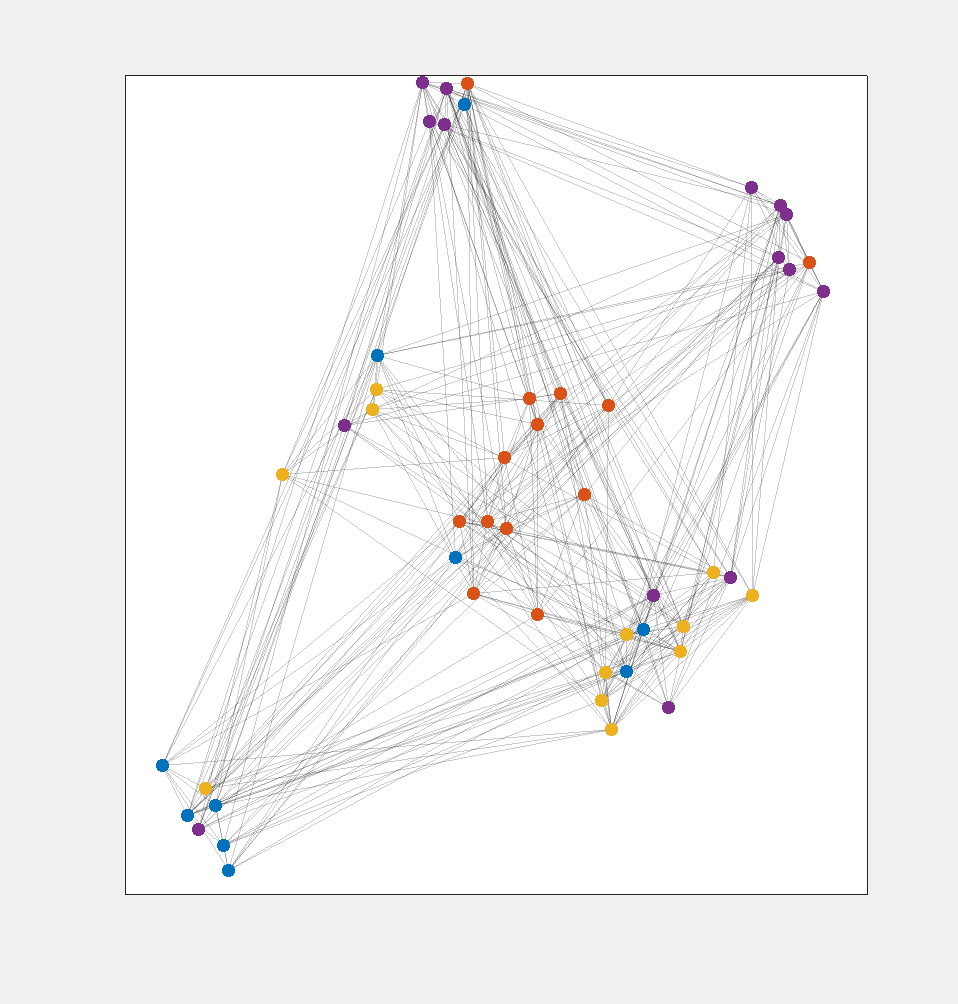

igraph.plot(adj, layout, membership=communities.fastgreedy, edgeAlpha=0.2);

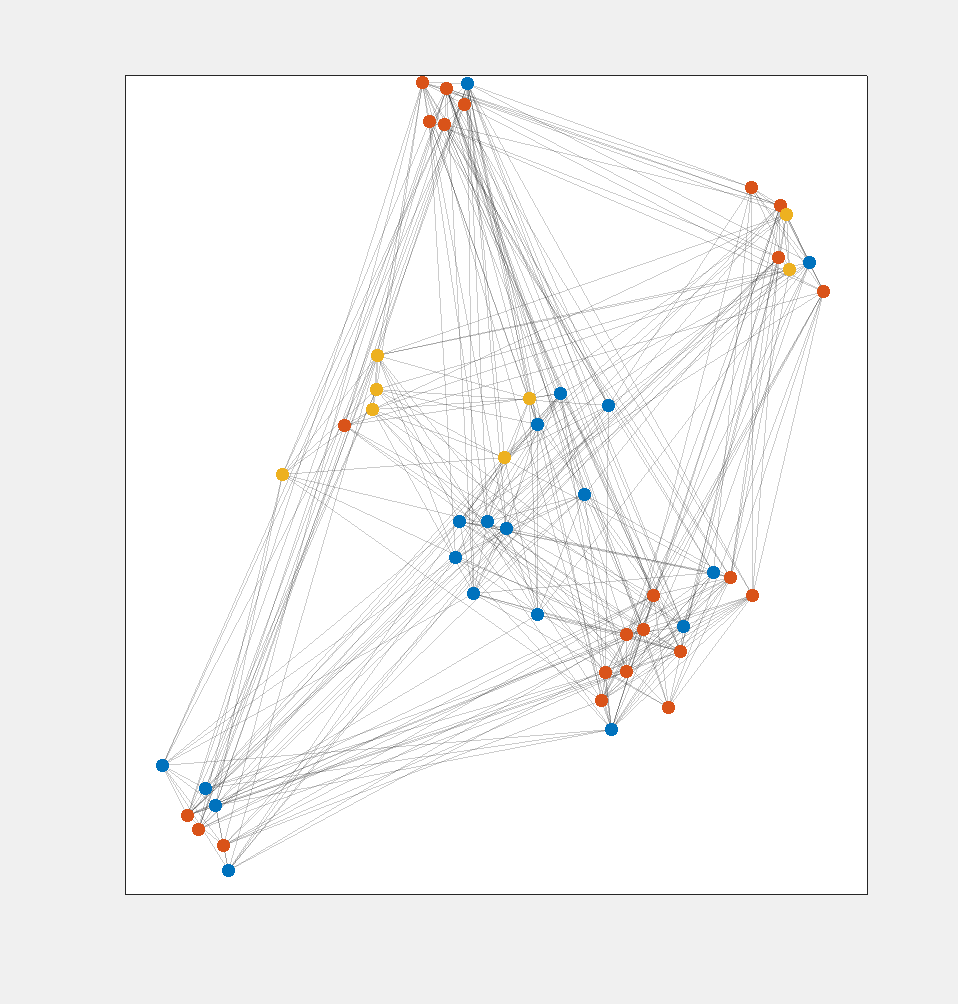

igraph.plot(adj, layout, membership=communities.walktrap, edgeAlpha=0.2);

#### Comparing the results

First, how similar are the two estimated partitions?

igraph.compare(communities.fastgreedy, communities.walktrap)

ans = 0.2852

By default `igraph.compare` uses normalized mutual information. See `help igraph.compare` for the list of available community comparison algorithms.

How similar was each partition to the original partition?

igraph.compare(groundTruth, communities.fastgreedy)

ans = 0.4500

igraph.compare(groundTruth, communities.walktrap)

ans = 0.3175

How did the two partitions do with respect to the modularity metric?

qTruth = igraph.modularity(adj, groundTruth);
igraph.modularity(adj, communities.fastgreedy) / qTruth

ans = 1.0538

igraph.modularity(adj, communities.walktrap) / qTruth

ans = 1.0064

Based off the membership comparison, we see the three partitions are not too similar yet they provide similar modularity, indicating there isn't a clear best partition.